## Opgaver

Opgave 12.74

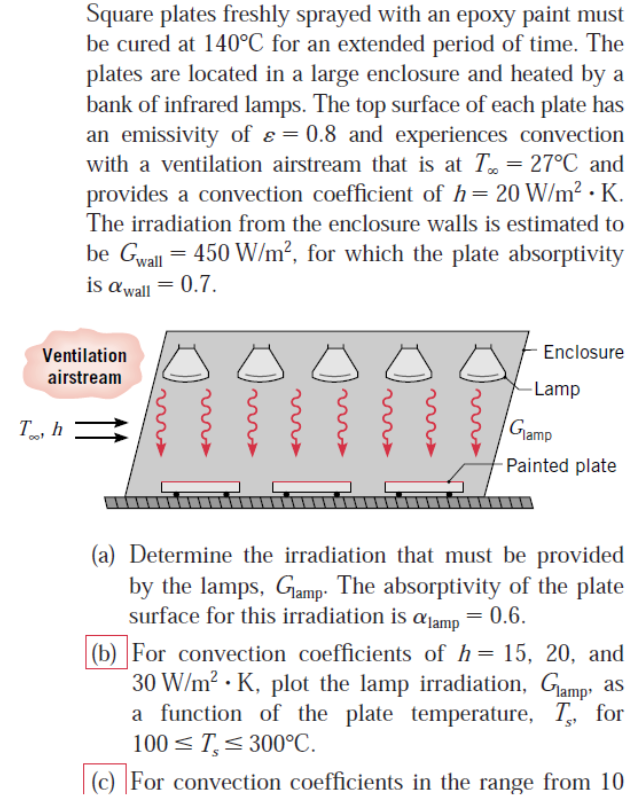

%Opg A
G_wall = 450

G_wall = 450

alpha_wall = 0.7

alpha_wall = 0.7000


alpha_lamp = 0.6

alpha_lamp = 0.6000

Sigma = 5.670374419e-8

Sigma = 5.6704e-08


h = 20

h = 20

T_inf = 27 +274

T_inf = 301

T_cure = 140 + 274

T_cure = 414


Emiss = 0.8

Emiss = 0.8000


%Vi stiller en energi ligning op for at finde gLamp. 

%Eind - Eud = 0
syms G_lamp

Es = Emiss * Sigma * T_cure^4 

Es = 1.3326e+03

q_mark_conv = h*(T_cure - T_inf)

q_mark_conv = 2260


Eind = alpha_wall * G_wall + alpha_lamp * G_lamp %Energi der kommer fra omgivelserne

$$Eind = \frac{3\,G_{\mathrm{lamp}}}{5}+315$$

EUd = q_mark_conv + Es %Energi der går tabt til konvektion 

EUd = 3.5926e+03


G_lamp = vpa(solve(0 == Eind - EUd, G_lamp), 5)

$$G\_lamp = 5462.7$$

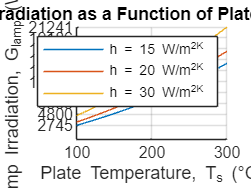

%Opg B
% Convection coefficients
h_values = [15, 20, 30];

% Temperature range
T_s_C = 100:5:300; % Plate temperature in Celsius
T_s = T_s_C + 273.15; % Convert to Kelvin

% Preallocate G_lamp matrix
G_lamp = zeros(length(h_values), length(T_s));

% Define symbolic variable
syms G_lamp_sym

% Calculate G_lamp for each h and T_s
for j = 1:length(h_values)
    h = h_values(j);
    for i = 1:length(T_s)
        T_cure = T_s(i);
        Es = Emiss * Sigma * T_cure^4;
        q_mark_conv = h * (T_cure - T_inf);
        Eind = alpha_wall * G_wall + alpha_lamp * G_lamp_sym;
        EUd = q_mark_conv + Es;
        G_lamp_solution = vpa(solve(0 == Eind - EUd, G_lamp_sym), 5);
        G_lamp(j, i) = double(G_lamp_solution);
    end
end

% Plot results
figure;
hold on;
for j = 1:length(h_values)
    plot(T_s_C, G_lamp(j, :), 'DisplayName', sprintf('h = %d W/m^2K', h_values(j)));
end
xlabel('Plate Temperature, T_s (°C)');
ylabel('Lamp Irradiation, G_{lamp} (W/m^2)');
title('Lamp Irradiation as a Function of Plate Temperature');
legend('show');
grid on;

% Manually set the y-axis ticks to prevent scientific notation
ax = gca;
ax.YAxis.Exponent = 0; % Prevent exponential notation on y-axis

% Generate custom y-ticks
yticks = linspace(min(G_lamp(:)), max(G_lamp(:)), 10);
yticklabels = arrayfun(@(x) sprintf('%.0f', x), yticks, 'UniformOutput', false);
set(ax, 'YTick', yticks, 'YTickLabel', yticklabels);

hold off;


% Plottet giver god mening. Vis vi skal have højere temepratur i pladen, så
% må vi skulle irradiere mere energi fra lampen! 
%Vis vi hever h så hæver vi mænden af energi som bliver ført væk fra pladen
%via konvektion, for at kompensere for det skal lampens irradiation være
%højere.


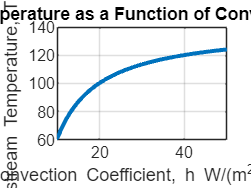

% Given constants
G_wall = 450;
alpha_wall = 0.7;
alpha_lamp = 0.6;
Sigma = 5.670374419e-8;
G_lamp = 3000; % Given lamp irradiation
Emiss = 0.8;

% Plate temperature (Celsius to Kelvin)
T_s = 140 + 273.15;

% Convection coefficients
h_values = 5:1:50; % Range of convection coefficients in W/m^2.K

% Preallocate T_x array
T_x = zeros(size(h_values));

% Calculate T_x for each h
for j = 1:length(h_values)
    h = h_values(j);
    
    % Radiation energy emission
    Es = Emiss * Sigma * T_s^4;
    
    % Convection heat transfer equation to solve for T_x
    syms T_x_sym
    q_mark_conv = h * (T_s - T_x_sym);
    Eind = alpha_wall * G_wall + alpha_lamp * G_lamp;
    EUd = q_mark_conv + Es;
    T_x_solution = vpa(solve(Eind == EUd, T_x_sym), 5);
    T_x(j) = double(T_x_solution);
end

% Convert T_x from Kelvin to Celsius
T_x_C = T_x - 273.15;

% Plot results
figure;
plot(h_values, T_x_C, 'LineWidth', 2);
xlabel('Convection Coefficient, h W/(m^2 * K)');
ylabel('Airstream Temperature, T_x (°C)');
title('Airstream Temperature as a Function of Convection Coefficient');
xlim([10, 50])
grid on;

Opgave 12.79

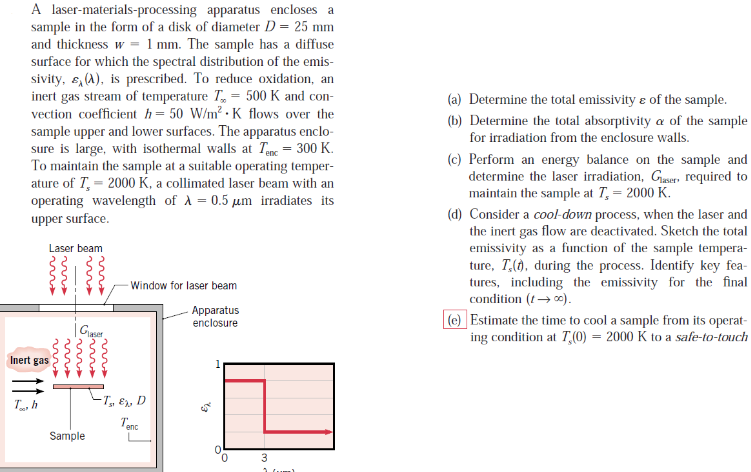

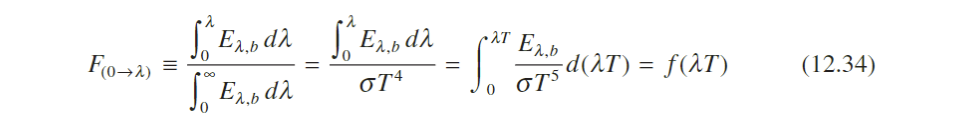

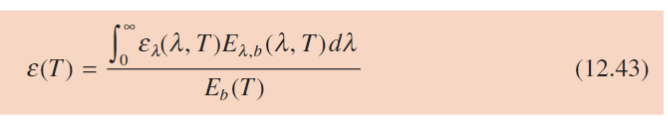

clear all
D = 0.025

D = 0.0250

w = 0.001

w = 1.0000e-03

T_inf = 500

T_inf = 500

h = 50

h = 50

T_enc = 300

T_enc = 300

T_s = 2000

T_s = 2000

lambda = 0.5 

lambda = 0.5000

%Nu begynder det at blive træls


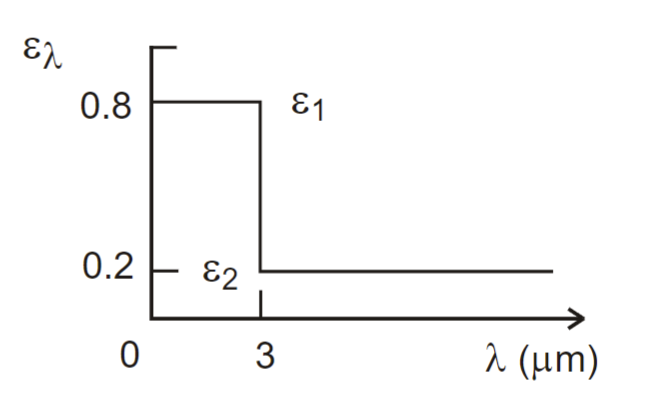

%dette er hvordan emmisiviiteten af overfladen ændre sig i forhold til
%lambda. Det ville sige at fra 0-3 um er epsilon = 0.8 og fra 3 til inf er
%lambda lig 0.2 Vi går altsa fra 0, til vi ender ved det første skift af
%spektratet så fra 0 til gamma_1 og har epsilon 1, og så fra den anden vej
%fra ind til 3 har vi gamma _1 og epsilon 2. Summen af de to skalaret med deres spektrums energi band funktioner 
%gir den totale emmisivitet. så vi ganger vores Ts med lamba_1 for at få
%gamma*T for at fin band funktionens værdig fra tabel 12.2

T_s * 3

ans = 6000


F_0_to_lambda = 0.737818

F_0_to_lambda = 0.7378


%Da de ligger samme stid så er F_0_to_lambda det samme for bægge. 
epsilon_1 = 0.8

epsilon_1 = 0.8000

epsilon_2 = 0.2

epsilon_2 = 0.2000



epsilon = epsilon_1*F_0_to_lambda+epsilon_2*(1-F_0_to_lambda)

epsilon = 0.6427

%(1-F_0_to_lambda) da vi kigger fra højre til venstre da det er nemmere. 

%opg b)
%Vi absorbere i samme spektrum som vi emmisere, så epsilon_1 og 2 er valide
%lambda er også stadig rigtigt. da vi nu kigger udefra og ind, så i stedet
%for at finde band funktionens værdig med overflade temperaturen, så kigger
%vi fra det der ligge omkring, og bruger dets temperatur.
T_enc = 300

T_enc = 300


T_enc = 300 * 3

T_enc = 900

F_0_to_lambda_enc = 0.000250

F_0_to_lambda_enc = 2.5000e-04


alpha_enc = epsilon_1*F_0_to_lambda_enc+epsilon_2*(1-F_0_to_lambda_enc)

alpha_enc = 0.2002


%opg c)
%Da laseren er monochromatisk hvilket ville sige at den kun emmisere i et
%spektrum, så kan vi bare sige at alpha = 0.8 (da 0.5 um ligger ved epsilon
% = 0.8) 
alpha_laser = 0.8

alpha_laser = 0.8000

syms G_las
Sigma = 5.670374419e-8 %boltzman konstant

Sigma = 5.6704e-08


%Total energy ind - total energy ud = 0
eq = alpha_laser * G_las + 2*alpha_enc*Sigma*T_enc^4 - 2*epsilon*Sigma*T_s^4 - 2*h*(T_s - T_inf)

$$eq = \frac{4\,G_{\mathrm{las}}}{5}-\frac{357693864727048907}{274877906944}$$


G_laser = vpa(solve(eq == 0, G_las), 5) %I Watt

$$G\_laser = 1.6266e+6$$


G_laser_kw = G_laser / 1000 %I kW

$$G\_laser\_kw = 1626.603374129772186279296875$$


%Arealet
A = pi*(0.025/2)^2 

A = 4.9087e-04

vpa(G_laser * A, 5)

$$ans = 798.46$$


%opg d)
% I og med at temperaturen falder så falder emmisiviteten og så så falder
% raten af emmisionen, det ville sige at jo lavere temperaturen er, jo
% lavere er emmisiviteten, og jo langsomere går afkølingen. 

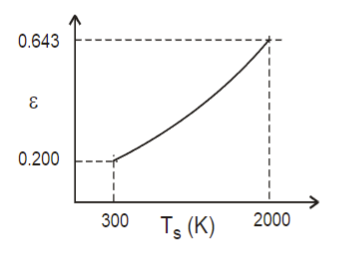

## Figurer og tabeller